clear

% RRT:
KD_RRT_Star_Time  = [];
KD_iter           = [];
IsDebug           = false;

% Printing:
sampled_start_pts = [];
[printing_path_checkpoints, printing_progress] = Printing();

for ith_start = 1:10000 % number of starting points to grow RRT*
    [rand_start_pt, current_IRM] = Fake_sampleIRM(printing_path_checkpoints(1,:), printing_progress(1), IsDebug);
    sampled_start_pts            = [sampled_start_pts; rand_start_pt];
end
if IsDebug
    scatter(sampled_start_pts(:,1), sampled_start_pts(:,2),'filled', 'MarkerFaceColor', '#77AC30')
    current_IRM_plot = fill(current_IRM(1,:), current_IRM(2,:), 'b', 'FaceAlpha', 0.2, 'EdgeColor',"none");
    delete(current_IRM_plot);
end

parfor idx = 1:length(sampled_start_pts(:,1))
    % Init:
    KDRRT                           = CLS_KDRRTStar;
    KDRRT.IsDEBUG                   = IsDebug;
    KDRRT.NN_method                 = 'KDTree_angle_diff_sq_norm';
    KDRRT.s_f                       = max(printing_progress);
    KDRRT.r_start                   = sampled_start_pts(idx,:);
    KDRRT.printing_path_checkpoints = printing_path_checkpoints;
    KDRRT.printing_progress         = printing_progress;
    
    % Build Obstacles:
%     [boundaries, n_obs_vertices, obs_vertices] = Obstacles(5);
%     hold on
    
    tic;
    [path, ite] = KDRRT.RRT_Star
    time = toc;
    disp(['Trial ' + string(idx) + ' Found path in ' + string(ite) + ' iterations.'])
    KD_iter          = [KD_iter, ite];
    KD_RRT_Star_Time = [KD_RRT_Star_Time, time];
end

Trial 1 Found path in 92 iterations.
Trial 126 Found path in 97 iterations.
Trial 251 Found path in 104 iterations.
Trial 376 Found path in 176 iterations.
Trial 2 Found path in 107 iterations.
Trial 3 Found path in 183 iterations.
Trial 4 Found path in 105 iterations.
Trial 5 Found path in 86 iterations.
Trial 6 Found path in 64 iterations.
Trial 7 Found path in 117 iterations.
Trial 8 Found path in 119 iterations.
Trial 127 Found path in 81 iterations.
Trial 128 Found path in 109 iterations.
Trial 129 Found path in 127 iterations.
Trial 130 Found path in 92 iterations.
Trial 131 Found path in 90 iterations.
Trial 132 Found path in 94 iterations.
Trial 133 Found path in 71 iterations.
Trial 134 Found path in 158 iterations.
Trial 252 Found path in 95 iterations.
Trial 253 Found path in 165 iterations.
Trial 254 Found path in 161 iterations.
Trial 255 Found path in 109 iterations.
Trial 256 Found path in 113 iterations.
Trial 257 Found path in 105 iterations.
Trial 377 Found path in 11

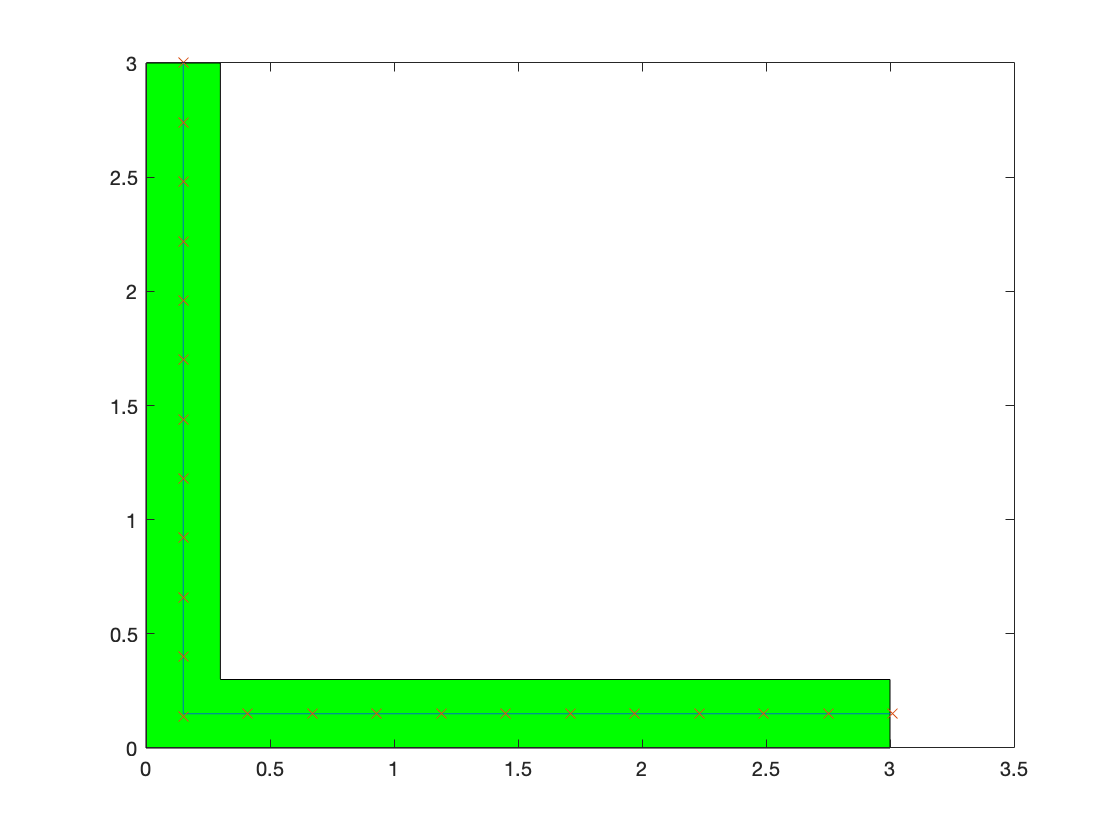

hold off

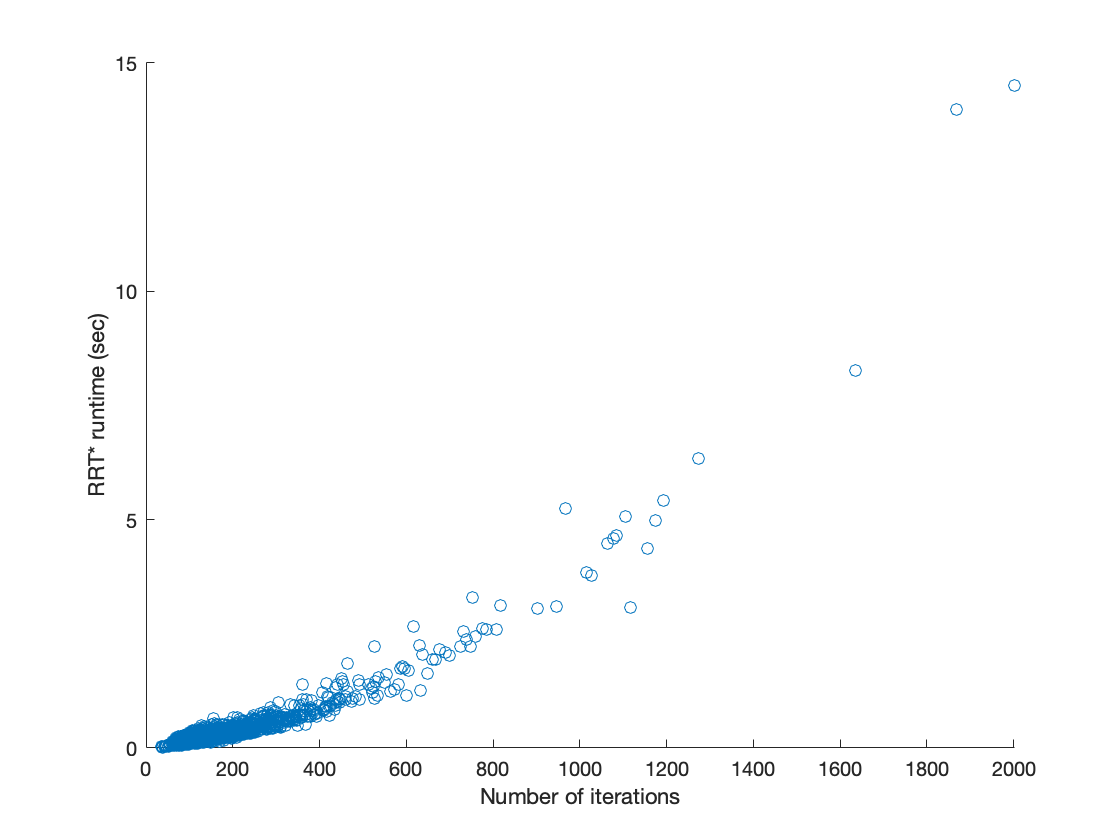

scatter(KD_iter, KD_RRT_Star_Time)
xlabel('Number of iterations')
ylabel('RRT* runtime (sec)')